a)  Describe, develop, and demonstrate code which builds a Manhattan-style grid street network. The network’s junctions should constitute an n×ngrid, where n is a parameter. The ‘horizontal’/‘vertical’ distance between neighbouring junctions is the same, and initially all streets should be two-way.

n = 10; % the number of nodes along an edge
L = 0.2; % the grid "pitch" e.g. the length of a street
A =-L*delsq(numgrid('S',n+2)); % adjacency matrix
G = digraph(A,'omitselfloops');
h = plot(G);
h.XData = L*floor((0:99)/10);
h.YData = L*rem((0:99), 10);
axis equal

b) Describe, develop, and demonstrate code which builds a new network in which the midpoint of each edge is a new node which will model the origin of the demand on that street.

function [A, v] = street_network(n, L)
    % G: MATLAB graph object
    % vec1: Vector of starting nodes
    % vec2: Vector of target nodes
    A =-L*delsq(numgrid('S',n+2)); % adjacency matrix
    smallhalf = floor(n/2);
    bighalf = ceil(n/2);
    
    % Initialize an empty vector to store nodes to remove
    v = zeros(1, smallhalf^2);
    index=1;
    Jump = n+bighalf;
    start = 2;
    stop = Jump - n;
    for i = 1:smallhalf
        for j = start:stop
            v(index) = (Jump * (i - 1)) + n + j;
            index=index+1;
        end
    end
    
    % remove nodes from the adjcency matrix
    for i = v
        A(i, :) = [];
        A(:, i) = [];
    end
end

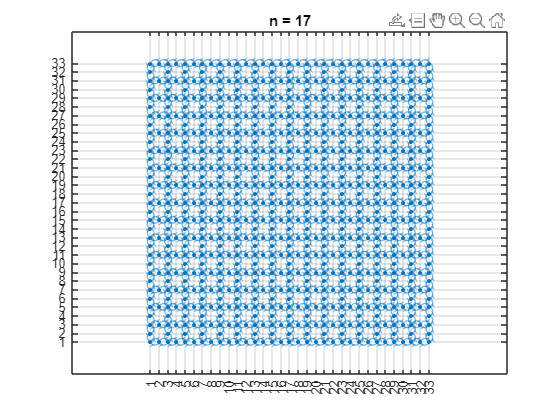

n = 33; % this has to be an odd number
L = 0.1; % the grid "pitch" e.g. the length of a street
[A, v] = street_network(n, L);
% plot and categorise the graph
[G, h] = plot_network(A, n, v, ['n = ', num2str(ceil(n/2))]); % function to remove repeated plotting lines
grid on;xticks(1:1:n);yticks(1:1:n);

c) Investigate designs for LTNs. You might want to try and make some streets one way (for example, by closing links A and B in the above figure) or blocking off the ends of streets at some junctions (for example, by closing links B and D in the above figure). Good designs will try to maximise the number of blocked-off streets (which are thus free of through traffic) and make large numbers of the remaining through streets one-way, in order to simplify the traffic flow. However, each street’s residents must retain a viable route to each corner of the network (and be able to return to their homes in the evening). Describe, develop, and demonstrate Matlab code which implements and displays your modified networks and which verifies the required connectivity. Note: highest marks will be reserved for solutions that work for any value of n, but if you find that too hard, setting n to a fixed value larger or equal to 10 is fine. (10 marks)

# Function for categorising the graph for later manipulation

[cornerNodes, degree3or4Nodes, streetNodes, allNodes, G] = categorise_graph(G, h, n);

function [cornerNodes, degree3or4Nodes, streetNodes, allNodes, G] = categorise_graph(G, h, n)
    %CATEGORISEGRAPH creates vectors containing the street and corner nodes,
    % classifies edges inside G.Edges table
    
    % G = graph
    % h = plot with x and y coordinates
    % n = key parameter in size of graph
    
    % categorise nodes
    smallhalf = floor(n/2);
    bighalf = ceil(n/2);
    cornerNodes = [1, n, ((n*smallhalf) + (bighalf*smallhalf) + 1), (n*bighalf) + (bighalf*smallhalf)];
    totalDegree = indegree(G) + outdegree(G);
    % Logical indexing
    isCornerNode = ismember(1:numnodes(G), cornerNodes);
    isDegree3or4 = totalDegree == 6 | totalDegree == 8;
    isStreetNode = totalDegree == 4 & ~isCornerNode';
    degree3or4Nodes = find(isDegree3or4);
    streetNodes = find(isStreetNode);
    allNodes = 1:numnodes(G); 
    
    % Categorise edges
    edgeRows = strings(numedges(G), 1);
    edgeCols = strings(numedges(G), 1);
    edgeDirections = strings(numedges(G), 1);
    for k = 1:numedges(G)
        src = G.Edges.EndNodes(k, 1); % Source node
        tgt = G.Edges.EndNodes(k, 2); % Target node
    
        % Get the coordinates of the source and target nodes
        x1 = h.XData(src);
        y1 = h.YData(src);
        x2 = h.XData(tgt);
        y2 = h.YData(tgt);
    
        % Classify the edge based on the coordinates
        if y1 == y2  % Same row -> Horizontal edge (Row)
            % The edge belongs to the row determined by y1 (or y2)
            edgeRows(k) = num2str(y1);  % Row number (Y-coordinate as string)
            edgeCols(k) = [num2str(x1) '->' num2str(x2)];  % Not applicable for columns
    
            % Determine the direction: left to right or right to left
            if x1 < x2
                edgeDirections(k) = "Left to Right";
            elseif x1 > x2
                edgeDirections(k) = "Right to Left";
            end
        elseif x1 == x2  % Same column -> Vertical edge (Column)
            % The edge belongs to the column determined by x1 (or x2)
            edgeCols(k) = num2str(x1);  % Column number (X-coordinate as string)
            edgeRows(k) = [num2str(y1) '->' num2str(y2)];  % Not applicable for rows
    
            % Determine the direction: up to down or down to up
            if y1 < y2
                edgeDirections(k) = "Down to Up";
            elseif y1 > y2
                edgeDirections(k) = "Up to Down";
            end
        end
    end
    
    % Add the row, column, and direction information as new columns in the G.Edges table
    G.Edges.y = edgeRows;
    G.Edges.x = edgeCols;
    G.Edges.direction = edgeDirections;
end

# Design 1 - Ring Road (Equal Weights)

A_d1 = A;
% make one way streets
for i = 1:height(G.Edges)
    if ismember(G.Edges.y(i), ["5", "9", "13", "17"]) && G.Edges.direction(i) == "Left to Right"
        A_d1(G.Edges.EndNodes(i,1), G.Edges.EndNodes(i,2)) = 0;
    end
    if ismember(G.Edges.y(i), ["3", "7", "11", "15", "19"]) && G.Edges.direction(i) == "Right to Left"
        A_d1(G.Edges.EndNodes(i,1), G.Edges.EndNodes(i,2)) = 0;
    end
    if ismember(G.Edges.x(i), ["5", "9", "13", "17"]) && G.Edges.direction(i) == "Up to Down"
        A_d1(G.Edges.EndNodes(i,1), G.Edges.EndNodes(i,2)) = 0;
    end
    if ismember(G.Edges.x(i), ["3", "7", "11", "15", "19"]) && G.Edges.direction(i) == "Down to Up"
        A_d1(G.Edges.EndNodes(i,1), G.Edges.EndNodes(i,2)) = 0;
    end
end

% Create a new graphs and check connections -------------
[G_1, h_1] = plot_network(A_d1, n, v, 'Design 1');
viable_route(G_1, allNodes, cornerNodes);
% Find number of links removed from the orginal design ---------------------------------
Linksremoved = height(G.Edges) - height(G_1.Edges);
disp(['Number of Edges removed:', mat2str(Linksremoved)]);

# Design 2 - Ring Road (Reduced Weights)

A_d2 = A_d1;
% make the ring road cheaper
for i = 1:height(G.Edges)
    if ismember(G.Edges.y(i), ["1", "21"])
        A_d2(G.Edges.EndNodes(i,1), G.Edges.EndNodes(i,2)) = 0.01;
    end
    if ismember(G.Edges.x(i), ["1", "21"])
        A_d2(G.Edges.EndNodes(i,1), G.Edges.EndNodes(i,2)) = 0.01;
    end
end
[G_2, h_2] = plot_network(A_d2, n, v, 'Design 2');
viable_route(G_2, allNodes, cornerNodes);

# Design 3 - Ring Road with Cut Throughs

A_d3 = A;
for i = 1:height(G.Edges)
    if ismember(G.Edges.y(i), ["5", "9", "13", "17"]) && G.Edges.direction(i) == "Left to Right"
        A_d3(G.Edges.EndNodes(i,1), G.Edges.EndNodes(i,2)) = 0;
    end
    if ismember(G.Edges.y(i), ["3", "7", "15", "19"]) && G.Edges.direction(i) == "Right to Left"
        A_d3(G.Edges.EndNodes(i,1), G.Edges.EndNodes(i,2)) = 0;
    end
    if ismember(G.Edges.x(i), ["5", "9", "13", "17"]) && G.Edges.direction(i) == "Up to Down"
        A_d3(G.Edges.EndNodes(i,1), G.Edges.EndNodes(i,2)) = 0;
    end
    if ismember(G.Edges.x(i), ["3", "7", "15", "19"]) && G.Edges.direction(i) == "Down to Up"
        A_d3(G.Edges.EndNodes(i,1), G.Edges.EndNodes(i,2)) = 0;
    end
end

% Create a new graphs and check connections -------------
[G_3, h_3] = plot_network(A_d3, n, v, 'Design 3');
viable_route(G_3, allNodes, cornerNodes);
% Find number of links removed from the orginal design ---------------------------------
Linksremoved = height(G.Edges) - height(G_3.Edges);
disp(['Number of Edges removed:', mat2str(Linksremoved)]);

# Design 4 - Deadends

A_d4 = A;
% creating deadends-----------------------------------------------------------
vector = [];
for i = 1:height(G.Edges)
    if ismember(G.Edges.y(i), ["2->3", "4->5", "6->7", "8->9", "10->11", "12->13", "14->15", "16->17", "18->19", "20->21"]) && ~ismember(G.Edges.x(i), ["1", "21"])
        % add the endnodes to my vector list
        vector = [vector; [G.Edges.EndNodes(i,1), G.Edges.EndNodes(i,2)]];
    end
end
A_d4 = makedeadends(A_d4, vector);

% Create a new graphs and check connections -------------
[G_4, h_4] = plot_network(A_d4, n, v, 'Design 4');
viable_route(G_4, allNodes, cornerNodes);
% Find number of links removed from the orginal design ---------------------------------
Linksremoved = height(G.Edges) - height(G_4.Edges);
disp(['Number of Edges removed:', mat2str(Linksremoved)]);

# Design 5 - Deadends with One ways

A_d5 = A_d4;
% creating one way streets --------------------------------------
for i = 1:height(G.Edges)
    if ismember(G.Edges.y(i), ["5", "9", "13", "17"]) && G.Edges.direction(i) == "Left to Right"
        A_d5(G.Edges.EndNodes(i,1), G.Edges.EndNodes(i,2)) = 0;
    end
    if ismember(G.Edges.y(i), ["3", "7", "11", "15", "19"]) && G.Edges.direction(i) == "Right to Left"
        A_d5(G.Edges.EndNodes(i,1), G.Edges.EndNodes(i,2)) = 0;
    end
end

% Create a new graphs and check connections -------------
[G_5, h_5] = plot_network(A_d5, n, v, 'Design 5');
viable_route(G_5, allNodes, cornerNodes);
% Find number of links removed from the orginal design ---------------------------------
Linksremoved = height(G.Edges) - height(G_5.Edges);
disp(['Number of Edges removed:', mat2str(Linksremoved)]);

# Design 6 - Maximum Deadends

A_d6 = A;
vector = [];
for i = 1:height(G.Edges)
    if ismember(G.Edges.y(i), "1->2") && ~ismember(G.Edges.x(i), ["1", "21"])
        % add the endnodes to my vector list
        vector = [vector; [G.Edges.EndNodes(i,1), G.Edges.EndNodes(i,2)]];
    end
    if ismember(G.Edges.x(i), ["2->3", "3->4", "6->7", "7->8", "10->11", "11->12", "14->15", "15->16", "18->19", "19->20"]) && ~ismember(G.Edges.y(i), ["1", "21"])
        vector = [vector; [G.Edges.EndNodes(i,1), G.Edges.EndNodes(i,2)]];
    end
end
A_d6 = makedeadends(A_d6, vector);

% Create a new graphs and check connections -------------
[G_6, h_6] = plot_network(A_d6, n, v, 'Design 6');
viable_route(G_6, allNodes, cornerNodes);
% Find number of links removed from the orginal design ---------------------------------
Linksremoved = height(G.Edges) - height(G_6.Edges);
disp(['Number of Edges removed:', mat2str(Linksremoved)]);

function viable_route(G, vec1, vec2)
    % G: MATLAB graph object
    % vec1: Vector of starting nodes
    % vec2: Vector of target nodes

    % Compute the distance matrix
    D = distances(G);

    % Check if every node in vec1 can reach any node in vec2
    forward = all(all(D(vec1, vec2) < Inf, 2));

    % Check if every node in vec2 can reach any node in vec1
    backward = all(all(D(vec2, vec1) < Inf, 2));

    disp(['Can travel from all street nodes to all corner nodes: ', mat2str(forward)]);
    disp(['Can travel from all corner nodes to all street nodes: ', mat2str(backward)]);
end


function [A] = makedeadends(Adj,vector)
% Adj is the adjacency matrix
% vector is the n by 2 list of node connections to cut 
n1 = vector(:, 1); % Source nodes
n2 = vector(:, 2); % Target nodes

% Set the connections in the adjacency matrix to zero
Adj(sub2ind(size(Adj), n1, n2)) = 0;
Adj(sub2ind(size(Adj), n2, n1)) = 0;

A = Adj;
end

d) Let us suppose that all travellers take the shortest path from their residence to their respective destination (although noting that depending how many links you have deleted — that shortest path may not be unique). Also, for simplicity, you may assume that each street generates exactly the same demand to each of the four corners of the network. Describe, develop, and demonstrate Matlab code which computes the traffic flow on each street for your proposed LTN design. How do flows compare with the setting where no LTN interventions are made? Discuss briefly possible trade-offs in your design: e.g., close off fewer streets, and maybe improve the capacity of others? (4 marks)

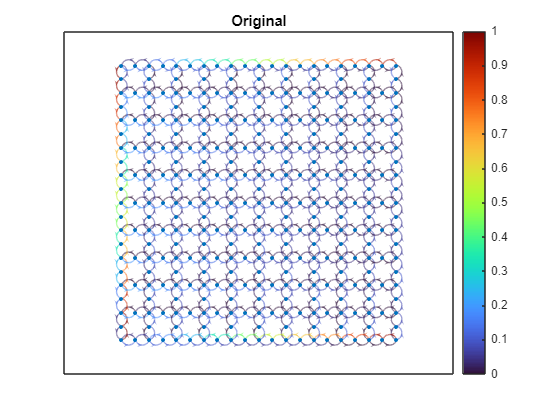

% 1 for plotting journeys home (to home), 1 for plotting journeys away (to
% work) and 3 for both
plot_edgeheatmap(G, streetNodes, cornerNodes, n, v, 'Original', 3)

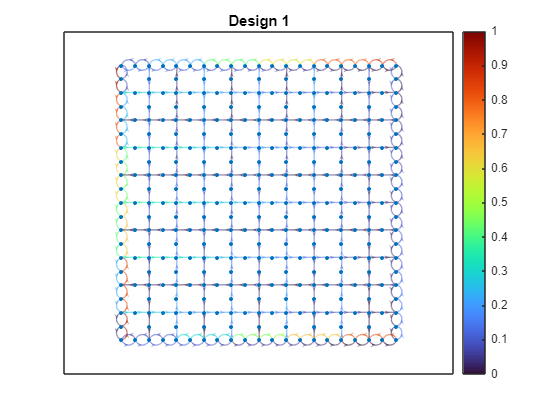

plot_edgeheatmap(G_1, streetNodes, cornerNodes, n, v, 'Design 1', 3)

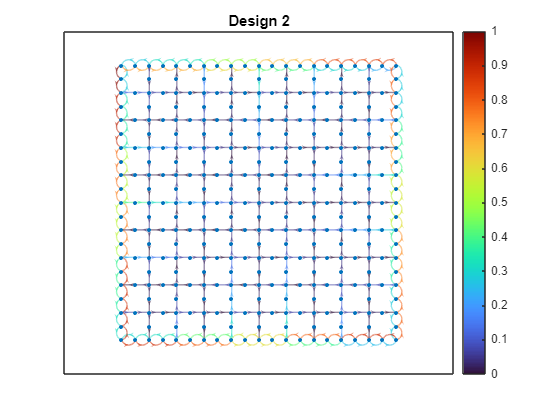

plot_edgeheatmap(G_2, streetNodes, cornerNodes, n, v, 'Design 2', 3)

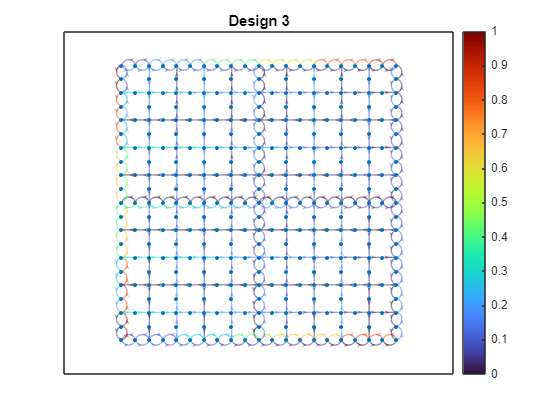

plot_edgeheatmap(G_3, streetNodes, cornerNodes, n, v, 'Design 3', 3)

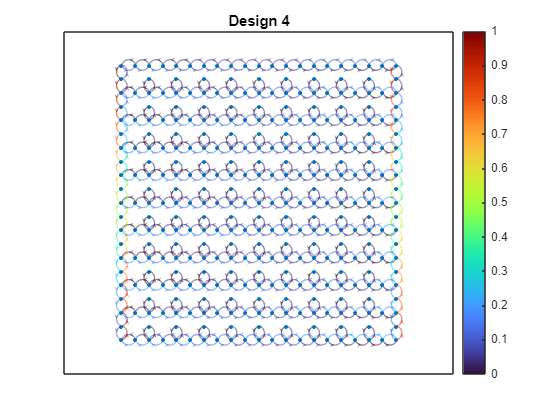

plot_edgeheatmap(G_4, streetNodes, cornerNodes, n, v, 'Design 4', 3)

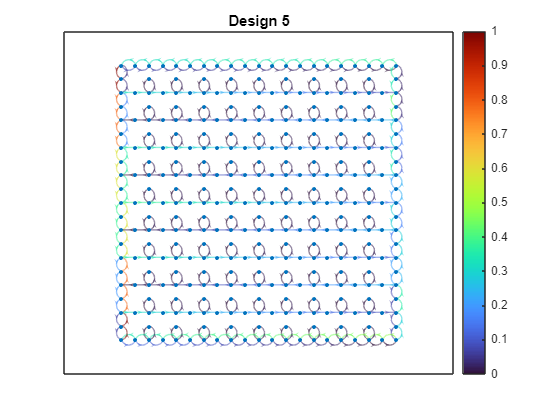

plot_edgeheatmap(G_5, streetNodes, cornerNodes, n, v, 'Design 5', 3)

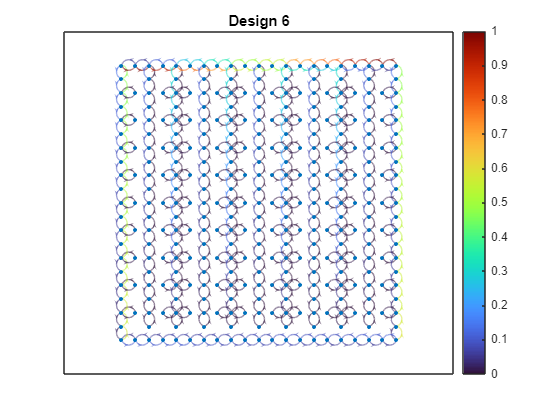

plot_edgeheatmap(G_6, streetNodes, cornerNodes, n, v, 'Design 6', 3)


plot_edgeheatmap(G, streetNodes, cornerNodes, n, v, 'Original - Home Journeys', 1)
plot_edgeheatmap(G, streetNodes, cornerNodes, n, v, 'Original - Away Journeys', 2)
plot_edgeheatmap(G, streetNodes, cornerNodes, n, v, 'Original - All Journeys', 3)
plot_edgeheatmap(G_6, streetNodes, cornerNodes, n, v, 'Design 6 - Home Journeys', 1)
plot_edgeheatmap(G_6, streetNodes, cornerNodes, n, v, 'Design 6 - Away Journeys', 2)
plot_edgeheatmap(G_6, streetNodes, cornerNodes, n, v, 'Design 6 - All Journeys', 3)

# Other functions

function [G, h] = plot_network(A, n, v, mytitle)
    % Plot grid networks, removing repeated lines of code from main
    % A = adjacency matrix
    figure;
    G = digraph(A, 'omitselfloops');
    h = plot(G);
    title(mytitle);
    [x, y] = meshgrid(1:n, 1:n);
    for i = v
        x(i) = [];
        y(i) = [];
    end
    h.XData = x(:);
    h.YData = y(:);
    axis equal
end

% function plot_edgeheatmap(G, streets, corners, n, v, mytitle)
%     %%% this function takes inputs of your network graph (G)
%     %%% source vector (s_v)
%     %%% target vector (t_v)
% 
%     s_v = repmat(corners, 1, length(streets)); % repeat %number of streetnodes% times
%     t_v = repmat(streets', 1, 4); % repeat 4 times because there are always four corners
% 
%     % finds the shortest path for each s-t pair and finds which edges in
%     % the network are used the most.
%     [P, d, ep] = arrayfun(@(s,t) shortestpath(G,s,t,'Method','positive'), s_v, t_v, UniformOutput=false);
% 
%     function count_arr = count_edge_hot(edges, num_edges)
%     % generate zero basic count_arr
%     count_arr = zeros(num_edges,1);
%     % zero check
%     if isempty(edges)
%     else
%         count_arr(edges{:}) = 1;
%     end
%     end
%     % edge count
%     e_c = arrayfun(@count_edge_hot, ep, height(G.Edges).*ones(size(d)), UniformOutput=false);
%     % this is currently an cell array
% 
%     % converting into a normal array
%     e_c_arr = zeros(height(G.Edges), length(s_v)^2);
% 
%     for i = 1:length(s_v)
%         e_c_arr(:,i) = cell2mat(e_c(i));
%     end
% 
%     hot_SGbase = sum(e_c_arr, 2);
% 
%     % normalise this
%     max_hot = max(hot_SGbase);
%     min_hot = min(hot_SGbase);
% 
%     norm_e_hot = (hot_SGbase - min_hot)./(max_hot-min_hot);
% 
%     [x, y] = meshgrid(1:n, 1:n);
%     for i = v
%         x(i) = [];
%         y(i) = [];
%     end
%     figure;
%     colormap('turbo'); 
%     h = plot(G, EdgeCData=norm_e_hot);
%     title(mytitle);
%     colorbar()
%     h.XData = x(:);
%     h.YData = y(:);
%     axis equal
% end

function plot_edgeheatmap(G, streets, corners, n, v, mytitle, flag)
    %%% this function outputs edge heatmap
    %%% source vector (s_v) - streetNodes
    %%% target vector (t_v) – cornerNodes
    src = repmat(corners, 1, length(streets)); % reshape
    tgt = repmat(streets', 1, 4); % reshape
    bothways = [src, tgt; tgt, src]; % reshape for finding forward and return journeys

    % find the shortest path for each source and target pair, find which edges are
    % used most
    if flag == 1
        [P, d, ep] = arrayfun(@(s,t) shortestpath(G,s,t,'Method','positive'), src, tgt, UniformOutput=false);
    elseif flag == 2
        [P, d, ep] = arrayfun(@(s,t) shortestpath(G,s,t,'Method','positive'), tgt, src, UniformOutput=false);
    elseif flag == 3
        [P, d, ep] = arrayfun(@(s,t) shortestpath(G,s,t,'Method','positive'), bothways(1, :), bothways(2, :), UniformOutput=false);
    end

    function countArray = countEdgeHot(edges, num_edges)
    % generate zero basic count_arr
    countArray= zeros(num_edges,1);
    % check if 0
    if isempty(edges)
    else
        countArray(edges{:}) = 1;
    end
    end
    % edge count
    edgeCount = arrayfun(@countEdgeHot, ep, height(G.Edges).*ones(size(d)), UniformOutput=false);
    
    % convert to normal array
    edgeCountArray = zeros(height(G.Edges), length(src)^2);

    for i = 1:length(src)
        edgeCountArray(:,i) = cell2mat(edgeCount(i));
    end
    
    hotSGbase = sum(edgeCountArray, 2);
    
    % normalising
    maxHot = max(hotSGbase);
    minHot = min(hotSGbase);
    normHot = (hotSGbase - minHot)./(maxHot-minHot);

% plotting
    [x, y] = meshgrid(1:n, 1:n);
    for i = v
        x(i) = [];
        y(i) = [];
    end
    figure;
    colormap('turbo'); 
    h = plot(G, EdgeCData=normHot);
    title(mytitle);
    colorbar()
    h.XData = x(:);
    h.YData = y(:);
    axis equal
end